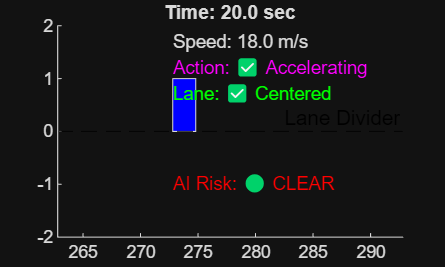

% STEP 1: Road and Ego Setup
road_width = 6;
lane_width = road_width / 2;
ego_pos = 0;
dt = 0.1;
v = 18;
t = 0:dt:20;
pos = zeros(size(t));
pos(1) = ego_pos;
vehicle_y_pos = 0;
lane_bounds = [-lane_width, lane_width];

% STEP 2: Obstacles
obstacle_positions = [30, 60];
lidar_range = 15;

% STEP 3: Data collection for LSTM
data = [];
labels = [];

% (Optional) Load AI model if exists
if exist('risk_predictor_lstm.mat', 'file')
    load('risk_predictor_lstm.mat', 'net');
else
    net = [];
end

for i = 2:length(t)
    % STEP 4: Detect distance to nearest obstacle
    nearest_dist = inf;
    for j = 1:length(obstacle_positions)
        dist = obstacle_positions(j) - pos(i-1);
        if dist >= 0 && dist < nearest_dist
            nearest_dist = dist;
        end
    end

    % STEP 5: Evasive Maneuver Logic
    if nearest_dist <= 5
        v = max(v - 2, 3);
        action = '🚨 Slowing & Passing Obstacle';
    elseif nearest_dist <= 18
        v = max(v - 1, 3);
        action = '⚠️ Decelerating';
    else
        v = min(v + 1, 18);
        action = '✅ Accelerating';
    end

    % STEP 6: Lane drift simulation
    if mod(i, 25) == 0
        vehicle_y_pos = vehicle_y_pos + 0.6;
    elseif mod(i, 37) == 0
        vehicle_y_pos = vehicle_y_pos - 0.6;
    end

    % Lane correction logic
    if vehicle_y_pos < lane_bounds(1) || vehicle_y_pos > lane_bounds(2)
        steer_action = '↩️ Correcting Lane';
        correction_rate = 0.2;
        vehicle_y_pos = vehicle_y_pos - correction_rate * sign(vehicle_y_pos);
        if abs(vehicle_y_pos) < 0.05
            vehicle_y_pos = 0;
        end
    else
        if abs(vehicle_y_pos) > 0.01
            vehicle_y_pos = vehicle_y_pos - 0.05 * sign(vehicle_y_pos);
        end
        steer_action = '✅ Centered';
    end

    % STEP 7: Update position
    pos(i) = pos(i-1) + v * dt;

    % STEP 8: Collect features
    current_features = [v, nearest_dist, abs(vehicle_y_pos)];
    data = [data; current_features];

    % Label risk (for training)
    if nearest_dist < 10 || abs(vehicle_y_pos) > lane_width
        labels = [labels; 1];
    else
        labels = [labels; 0];
    end

    % STEP 9: Predict risk using LSTM (if loaded)
    if ~isempty(net)
        X_new = num2cell(normalize(current_features') , [1]);
        prediction = classify(net, X_new);
        if prediction == categorical(1)
            ai_status = '🔴 RISK AHEAD';
        else
            ai_status = '🟢 CLEAR';
        end
    else
        ai_status = '⚠️ AI NOT LOADED';
    end

    % STEP 10: Plot Simulation
    clf;
    hold on;
    fill([-5, 200, 200, -5], [-3, -3, 3, 3], [0.9, 0.9, 0.9]);
    yline(0, '--k', 'Lane Divider');
    rectangle('Position', [pos(i), vehicle_y_pos-0.5, 2, 1], 'FaceColor', 'b');

    for j = 1:length(obstacle_positions)
        rectangle('Position', [obstacle_positions(j), -0.5, 2, 1], 'FaceColor', 'r');
    end

    % Show status
    text(pos(i), 1.7, ['Speed: ' num2str(v, '%.1f') ' m/s'], 'FontSize', 9);
    text(pos(i), 1.2, ['Action: ' action], 'FontSize', 9, 'Color', 'm');
    text(pos(i), 0.7, ['Lane: ' steer_action], 'FontSize', 9, 'Color', 'g');
    text(pos(i), -1.0, ['AI Risk: ' ai_status], 'FontSize', 9, 'Color', 'r');

    xlim([pos(i)-10, pos(i)+20]);
    ylim([-2, 2]);
    title(sprintf('Time: %.1f sec', t(i)));
    drawnow;
end


% STEP 11: Save data for training if needed
save('risk_data.mat', 'data', 'labels');
